Лабораторная работа № 3

P = 0:10

P =      0     1     2     3     4     5     6     7     8     9    10


T = [0 1 2 3 4 3 2 1 2 3 4]

T =      0     1     2     3     4     3     2     1     2     3     4



net  = newff([0  10] , [5  1],{'tansig' 'purelin'});

          See help for NEWFF to update calls to the new argument list.
 


Y = sim(net,P)

Y =     0.1260    0.0723   -0.0186   -0.3030   -0.4413   -0.8874   -1.3118   -1.1432   -0.4152   -0.2255   -0.4743


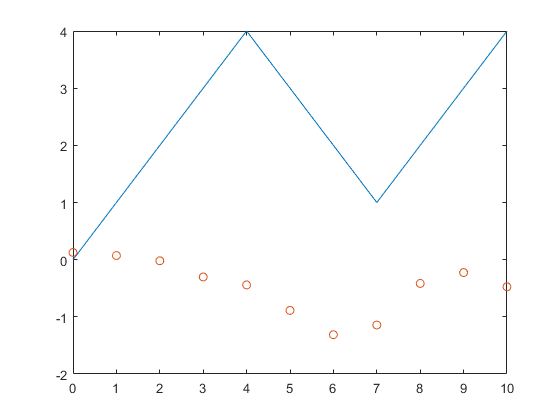

plot(P,T,P,Y,'o')

net.trainParam.epochs = 50

net =

    Neural Network
 
              name: 'Custom Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 16
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      <a href="matlab:doc nnproperty.net_inputConnect">inputConnect</a

net = train(net,P,T)

net =

    Neural Network
 
              name: 'Custom Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 16
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      <a href="matlab:doc nnproperty.net_inputConnect">inputConnect</a



Y = sim(net,P)

Y =     0.0000    1.0000    1.9998    3.0006    3.9577    3.1124    1.8571    1.1506    1.8577    3.1119    3.9585


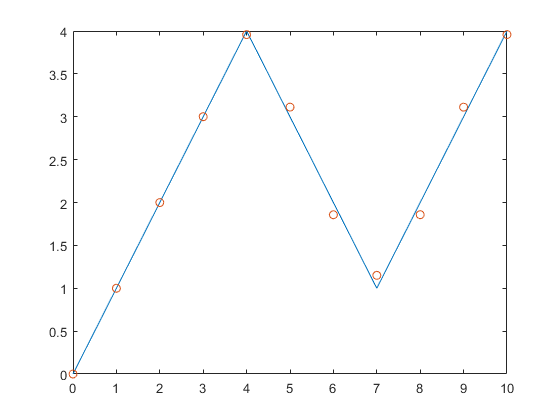

plot(P,T,P,Y,'o')   